# JMO Spectrum Library Documentation

Version 1.31, November 3, 2020

Julius Muschaweck, JMO GmbH, Zugspitzstr. 66, 82131 Gauting, Germany. julius@jmoptics.de

## Rationale

We deal routinely with spectra in illumination optics. We need to analyze LED spectra, compute color coordinates and color rendering values from spectra, integrate them, add spectra, multiply spectra with scalar weights and with other spectra (like transmission spectra), interpolate a given measured spectrum with non-equidistant wavelength values to a regular 1 nm array, and so on. 

In practice, this is tedious: spectra come in various formats, and the problem of dealing with two spectra als tabulated values which have two different sets of wavelengths is annoying. In addition, many colorimetric calculations, from computing simple x/y coordinates all the way to the color rendering index, are not easily accessable.

This open source Matlab library is designed to make these engineering tasks easy and transparent. Many routines are compatible with GNU Octave, and with Matlab for Mac and Linux. 

## License -- public domain

I release this software into the public domain under [CC0](https://creativecommons.org/publicdomain/zero/1.0/legalcode)

## Version history

Beta Version 1.32 March 20, 2021

    Added EvalSpectrum to evaluate a spectrum as a function

    Added MacAdamEllipse to compute MacAdam color difference ellipses

    ComputeSpectrumColorimetry now returns u,p, u', v'. And with optional 'XYZn' argument (the diffuse white in the scene), it returns also Lab and Luv.

Version 1.31 Nov. 3, 2020

    Stopped trying to keep the library entirely compatible to GNU Octave. Especially the `arguments` syntax for function parameter validation is just too valuable, and I try to put more effort into the functionality instead of testing with Octave.

    Added SolarSpectrum to return extraterrestrial and ground level solar spectra

    Added `'ColorFill' `option to PlotCIExyBorder

    Added `StockmanSharpe2000.mat `to provide these L, M and S cone sensitivities.

Version 1.3 July 18,.2020

    Revised PlanckSpectrum to include refractive index.

    Added RGBLEDSpectrum class to model spectra of RGB LEDs under actual operating conditions, based on data sheet and binning information only.

    Added ShiftToLDom function, shifting a spectrum such that the result has a desired dominant wavelength

Version 1.24, July 4, 2020

    Fixed bug in AddSpectra, where two spectra with different additional fields could not be added.

Version 1.23, Jan 25, 2020

    Fixed a bug in CRI (van Kries transformation was first computed but then ignored).

    Added IntegrateSpectrum, to integrate a spectrum, with an optional weighting spectrum 

Version 1.22, Jan 24, 2020

    Added ComputeSpectrumColorimetry, convenience function to compute XYZ, CCT and color rendering values in one call

    Added Vlambda, returning V(lambda), CIE 1924 as a spectrum

    Added PlotCIExyBorder, plotting the CIE x/y "color horseshoe", with optional ticks and other options

    MakeSpectrum now accepts optional Name/Value pairs to set fields like e.g. 'name'

    CCT and CCT_from_xy have additional return values `ok `and `errmsg`, to suppress errors and warnings if desired

Version 1.21, Jan 24, 2020

    Added CCT, convenience function to compute CCT from spectrum directly, not via x/y

    Added Example_WhiteLED.m as an example script composing a white LED from blue and yellow, with supporting spectra blue.sre and yellow.sre

    Added LDomPurity, to compute dominant wavelength and purity of a spectrum

    Added ReadLightToolsSpectrumFile, to read LightTools .sre files, as supplied by many LED vendors. Reads also simple ASCII 2-column tables with any text header

Version 1.2, Jan. 22, 2020

    Added CIE standard illuminants

    Added CRI (color rendering index) computations

    Added AssignNewWavelength function

Version 1.01, Oct. 13:

    Added WriteLightToolsSpectrumFile

Version 1.0, Sept. 9, 2019: Initial version

## Getting started

To define a spectrum and compute its CIE xy color coordinates, simply say

clear s;
s.lam = [360 830];
s.val = [1 1];
% this is a flat spectrum, known as CIE standard illuminant E. 
% By definition, it should have color coordinates x == y == 1/3-
s.XYZ = CIE1931_XYZ(s);
% This is a common pattern: Compute information from a spectrum, and then
% add this information to the same spectrum as an additional field
s

s = struct with fields:
    lam: [360 830]
    val: [1 1]
    XYZ: [1×1 struct]


s.XYZ

ans = struct with fields:
    X: 106.8654
    Y: 106.8569
    Z: 106.8919
    x: 0.3333
    y: 0.3333
    z: 0.3334


## Design decisions

### Spectrum

In this library, a *spectrum* is a struct with at least two fields named `lam` and `val`, which meet the following requirements:

- `lam` is a 1D vector of numeric values which are not complex, > 0, and strictly ascending

- `val` is a 1D vector of numeric values which are not complex.

- `lam `and `val `are of same length and have at least two elements

It is desirable for `lam `and `val `to be column vectors.

There is a function `rv = SpectrumSanityCheck(rhs)`, which tests all these requirements and, if met, returns the same struct except that `lam `and `val `are converted to column vectors if necessary.

A *spectrum* models the function *S(lambda)* which represents a physical scalar function of wavelength. Like spectral radiant flux, spectral irradiance, spectral radiant intensity, spectral radiance, spectral transmission, spectral absorption, spectral efficiency. The tabulated values in `val `are linearly interpolated. Outside the range given by `lam`*, * *S(lambda)* == 0. Accordingly, there are no spectra consisting of truly monochromatic lines in this library. If you want to approximate line spectra, make very narrow triangles. Spectra are continuous, except at the wavelength boundaries, where the jump to zero

`lam `is considered to have units of nanometers in all library functions that make use of this unit, e.g. color calculations.

Why structs and not classes? Classes are nice to guarantee that properties like `lam `and `val `always are present, and would allow methods which operate directly on spectra. However, structs are simpler and more versatile. I, as the library designer, cannot know which additional information a user (I myself, for example), wants to attach to a given spectrum. Name, date, name of LED, color coordinates and more. To make a spectrum s, I can simply say

clear s
s.lam = [360 830];
s.val = [1 1];
s.name = "CIE standard illuminant E";
s.hopp = "topp";
s

s = struct with fields:
     lam: [360 830]
     val: [1 1]
    name: "CIE standard illuminant E"
    hopp: "topp"


to give it an appropriate name and an arbitrary value in an arbitrary additional field. Of course, a user can always create a subclass to add properties to a given class, but it is just so much simpler to assign to an additional struct field in a single line. In my experience, these conventions for spectra are simple and few enough to be easily remembered and adhered to.

### Conventions

In my code, I like to have long unabbreviated variable and function names. Except for a few standards:

`rv` is my name for the return value of a function

`spec `is my name for a single spectrum argument of a function.

`lhs `and `rhs  `are short for 'left hand side' and 'right hand side', the arguments of a binary function.

Proper library function names start with capital letters, e.g. `MakeSpectrum`. Internal helper functions start with a small "i", e.g. `iLinInterpolProto`.

A spectrum struct is valid if it has fields lam and `val `which fulfill the requirements above. In addition, I assume a spectrum may have the following fields:

`name`*: * A short character string with a name. 

`description`*: *A longer character string with a description.

`XYZ`*: * A struct with tristimulus and color coordinate fields `X, Y, Z, x, y, z`, typically created by code like `s.XYZ = CIE1931_XYZ(s)`

## Function reference

### Alphabetic list

AddSpectra adds two spectra

AddWeightedSpectra adds multiple spectra with weights

AssignNewWavelength replaces the wavelength of a spectrum, interpolating the values correctly

CCT, convenience function to compute CCT from spectrum directly, not via x/y

CCT_from_xy computes correlated color temperature and uv-distance to Planck locus from spectrum

CIE1931_lam_x_y_z.mat contains CIE 1931 data for color matching functions, monochromatic border and Planck locus

CIE1931_XYZ computes CIE 1931 XYZ color coordinates and tristimulus values from spectrum

CIE_Illuminant returns a large selection of CIE standard illuminants

CIE_Illuminant_D computes the CIE standard daylight spectrum as function of color temperature

CODATA2018 returns a struct with CODATA 2018 values for relevant physical constants (speed of light, Boltzmann constant etc.)

ComputeSpectrumColorimetry, convenience function to compute XYZ, CCT and color rendering values in one call

CRI computes Color Rendering Index values according to CIE 13.3-1995

Example_WhiteLED.m as an example script composing a white LED from blue and yellow, with supporting spectra blue.sre and yellow.sre

EvalSpectrum evaluates a spectrum as a function of wavelength. Vector input is possible

GaussSpectrum creates a Gaussian spectrum for given mean and standard deviation

IntegrateSpectrum,  integrate a spectrum, with an optional weighting spectrum 

IsOctave determines if running on GNU Octave or Matlab

IsSpectrum checks if a spectrum is valid

LDomPurity, to compute dominant wavelength and purity of a spectrum

LinInterpol computes linear interpolation like `interp1, `but about five times faster on Matlab on Windows

LinInterpolAdd4Async computes linear interpolation of the sum of four functions

MakeSpectrum creates a valid spectrum from wavelength and value data

MultiplySpectra multiplies two spectra, e.g. an LED spectrum with a transmission spectrum

PlanckLocus returns a wealth of information about the Planck locus, including interpolation function objects and Judd lines of equal CCT

PlanckSpectrum creates a blackbody spectrum with various normalizations to choose from

PlotCIExyBorder, plotting the CIE x/y "color horseshoe", with optional ticks and other options

ReadLightToolsSpectrumFile, to read LightTools .sre files, as supplied by many LED vendors. Reads also simple ASCII 2-column tables with any text header

RGBLEDSpectrum is a class to model RGB LED spectra at operating conditions, based solely on data sheet information

ShiftToLDom shifts the wavelengths of a given spectrum such that a desired dominant wavelength results

SolarSpectrum returns various extraterrestrial and ground level solar spectra according to ASTM

SpectrumSanityCheck performs a detailed diagnosis if a spectrum fails to fulfill the requirements, returns a sanitized spectrum otherwise

TestLinInterpol tests the LinInterpol function

Vlambda, returning V(lambda), CIE 1924 as a spectrumCRI is a class for computing color rendering index values

WriteLightToolsSpectrumFile writes a spectrum to an ASCII file in LightTools® format.

## `AddSpectra`

Adds two spectra without weights. Convenience function with simpler interface than AddWeightedSpectra

% function rv = AddSpectra(lhs, rhs)

**Input:** `lhs, rhs`*: *Both must be valid spectra.

**Output:** `rv`*: *Sum of `rhs + lhs`. When both spectra do not overlap, the wavelength ranges are concatenated, and the range in between is padded with zero. If they do overlap, then `rv.lam` contains all values from both input spectra, with duplicate values removed, and what is added are the linearly interpolated values from both input spectra. Thus, the sum spectrum is a perfect model of the underlying continuous function which is the sum of the continuous, linearly interpolated input spectra.

Additional fields present in `lhs `or `rhs `will be stripped, `rv `will have only fields `lam `and `val.`

**Usage Example:**

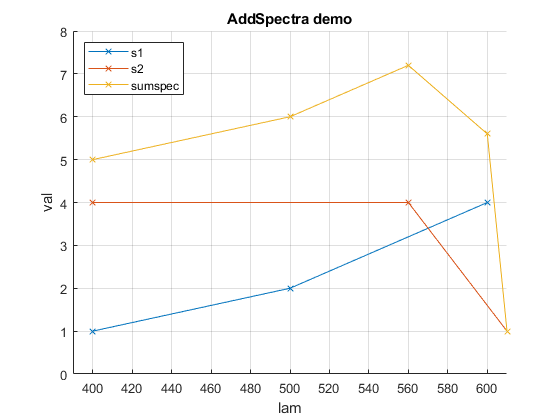

clear s1 s2 sumspec
s1 = MakeSpectrum([400,500,600],[1, 2, 4]);
s2 = MakeSpectrum([400,560,610],[4, 4, 1]);
sumspec = AddSpectra(s1,s2);
nfig = 1;
figure(nfig);
clf;
hold on;
plot(s1.lam, s1.val,'Marker','x');
plot(s2.lam, s2.val,'Marker','x');
plot(sumspec.lam, sumspec.val,'Marker','x');
legend({'s1','s2','sumspec'},'Location','NorthWest');
axis([390 610 0 8]);
grid on;
xlabel('lam');
ylabel('val');
title('AddSpectra demo');

## `AddWeightedSpectra`

Computes weighted sum of several spectra.

% function rv = AddWeightedSpectra(spectra,weights)

**Input:**

`spectra`: Nonempty *c*ell array of spectra

`weights`*: *Vector of numeric non-complex values, same length as `spectra`*.*

**Output:** `rv`*: *Weighted sum of input spectra. When spectra do not overlap, the wavelength ranges are concatenated, and the range in between is padded with zero. If they do overlap, then `rv.lam` contains all values from all input spectra, with duplicate values removed, and sorted, and what is added are the linearly interpolated values from all input spectra. Thus, the sum spectrum is a perfect model of the function which is the sum of the continuous, linearly interpolated input spectra.

Additional fields present in `spectra` will be stripped, `rv `will have only fields `lam `and `val`*.*

**Usage Example:**

Add a red, a green, and a blue spectrum created by GaussSpectrum

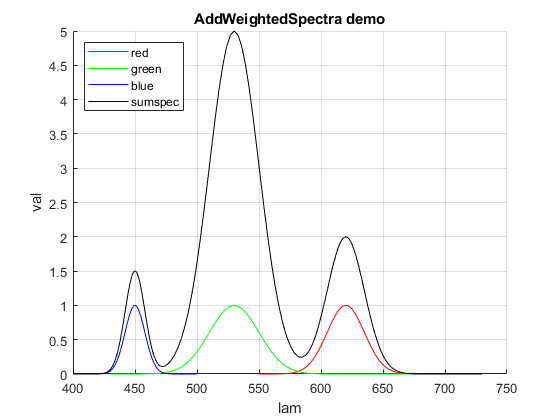

clear red green blue sumspec
red = GaussSpectrum(linspace(550,700),620,15);
green = GaussSpectrum(linspace(430,730),530,20);
blue = GaussSpectrum(linspace(400,500),450,8);
sumspec = AddWeightedSpectra({red, green, blue},[2, 5, 1.5]);
nfig = nfig + 1;
figure(nfig);
clf;
hold on;
plot(red.lam, red.val,'r');
plot(green.lam, green.val,'g');
plot(blue.lam, blue.val,'b');
plot(sumspec.lam, sumspec.val,'k');
legend({'red','green','blue','sumspec'},'Location','NorthWest');
grid on;
xlabel('lam');
ylabel('val');
title('AddWeightedSpectra demo');

## `AssignNewWavelength`

Assign a new wavelength vector to a spectrum, interpolating the old values.

% function rv = AssignNewWavelength(spectrum, lam_new)

**Input:**

`spectrum:` a spectrum

`lam_new:` the new wavelength array, ascending doubles.

**Output:**

`rv:` A copy of the old spectrum with all fields, but `lam `is replaced and `val `is interpolated. For `lam_new` values outside the old interval, `val(i) == 0`

**Usage Example:**

s_old = MakeSpectrum([400 500], [0 100]);
s_new = AssignNewWavelength(s_old, [450 451 452])

s_new = struct with fields:
    lam: [450 451 452]
    val: [50 51 52]


## `CCT`

convenience function to compute CCT from spectrum directly, not via x/y

% function [iCCT, dist_uv, ok, errmsg] = CCT(spectrum)

**Input:**

`spectrum:` a spectrum with fields lam and val

**Output:**

`iCCT: ` Correlated color temperature in Kelvin

`dist_uv: `Distance to Planck locus in u/v color space. When `dist_uv>0.05, `a warning is issued, when `dist_uv `> 0.09, an error. Positive when x/y is above Planck locus (on the "green" side), negative when below.

`ok: true` if CCT can be properly computed, i.e. `dist_uv <= 0.9` and CCT within 1000..Inf range. `false `if something went really wrong

`errmsg: `empty `'' `if everything is ok, `'error: ...' `if  `ok==false, 'warning: ...' `e.g. if `dist_uv > 0.05'`, which makes the CCT computation technically illegal.

If `ok` is not queried as a return value, warnings and errors are raised. If `ok `is queried, they are suppressed.

**Usage Example:**

test = CIE_Illuminant('D65'); % 6500K CIE daylight spectrum, slightly above Planck
[iCCT, dist_uv] = CCT(test) %#ok<ASGLU> % not exactly 6500, depends on step size of XYZ integration.

iCCT = 6.5008e+03

dist_uv = 0.0032

## `CCT_from_xy`

Compute correlated color temperature of an xy color point. Uses parabolic interpolation between nearest Planck locus points

% function [CCT, dist_uv, ok, errmsg] = CCT_from_xy(x,y)

**Input:** `x, y` scalar numbers, x/y color coordinates

**Output:** 

`CCT: ` Correlated color temperature in Kelvin

`dist_uv: `Distance to Planck locus in u/v color space. When `dist_uv>0.05, `a warning is issued, when `dist_uv `> 0.09, an error. Positive when x/y is above Planck locus (on the "green" side), negative when below.

`ok: true` if CCT can be properly computed, i.e. `dist_uv <= 0.9` and CCT within 1000..Inf range. `false `if something went really wrong

`errmsg: `empty `'' `if everything is ok, `'error: ...' `if  `ok==false, 'warning: ...' `e.g. if `dist_uv > 0.05'`, which makes the CCT computation technically illegal.

If `ok` is not queried as a return value, warnings and errors are raised. If `ok `is queried, they are suppressed.

**Usage Example:**

clear T pl jl uv den x y CCT dist_uv
T = 3456; 
pl = PlanckLocus;
jl = pl.JuddLine_func(T);
% compute uv coordinates for color point with CCT == T,
% 0.04 away from Planck
uv = [jl.u, jl.v] + 0.04 * [jl.du, jl.dv];
% compute xy coordinates by standard transformation 
den = 2*uv(1) - 8*uv(2) + 4;
x = 3*uv(1)/den;
y = 2 * uv(2) / den;
% compute CCT 
[iCCT, dist_uv] = CCT_from_xy(x,y);
iCCT - T % should be zero, is about 1.3 mK

ans = 0.0013

dist_uv - 0.04 % should be zero

ans = -4.3835e-07

## `CIE1931_lam_x_y_z.mat`

A .mat file which contains a struct named `'CIE1931XYZ' `with CIE 1931 data: x/y/z color matching functions, monochromatic border x/y coordinates with corresponding wavelengths, and coordinates of the Planck locus with corresponding absolute temperatures.

**Usage Example:**

clear CIE1931XYZ;
load('CIE1931_lam_x_y_z.mat','CIE1931XYZ')
CIE1931XYZ

CIE1931XYZ = struct with fields:
        lam: [471×1 double]
          x: [471×1 double]
          y: [471×1 double]
          z: [471×1 double]
    xBorder: [471×1 double]
    yBorder: [471×1 double]
    PlanckT: [1001×1 double]
    Planckx: [1001×1 double]
    Plancky: [1001×1 double]


### `CIE1931_XYZ`

Computes CIE 1931 color coordinates.

% function rv = CIE1931_XYZ(spec)

**Input: **`spec` is a *spectrum *struct, see above for requirements.

**Output:** A struct with fields `X Y Z x y z`. 

Capital   `X Y Z `are the CIE tristimulus values, i.e. the result of integrating `spec` with the CIE 1931 standard x y z color matching functions.

`x y z` are the corresponding color coordinates, `x = X / (X + Y + Z)`  etc.

**Usage example:**

clear s;
s.lam = [360 830];
s.val = [1 1];
% this is a flat spectrum, known as CIE standard illuminant E. 
% By definition, it should have color coordinates x == y == 1/3-
s.XYZ = CIE1931_XYZ(s);
% This is a common pattern: Compute information from a spectrum, and then
% add this information to the same spectrum as an additional field
s

s = struct with fields:
    lam: [360 830]
    val: [1 1]
    XYZ: [1×1 struct]


s.XYZ

ans = struct with fields:
    X: 106.8654
    Y: 106.8569
    Z: 106.8919
    x: 0.3333
    y: 0.3333
    z: 0.3334


## `CIE_Illuminant`

Returns CIE standard illuminants.

Available spectra are: 'A';'D65';'C';'E','D50';'D55';'D75';'FL1';'FL2';'FL3';'FL4';'FL5';'FL6';'FL7';'FL8';'FL9';'FL10';'FL11';'FL12';

'FL3_1';'FL3_2';'FL3_3';'FL3_4';'FL3_5';'FL3_6';'FL3_7';'FL3_8';'FL3_9';'FL3_10';'FL3_11';'FL3_12'; 'FL3_13';'FL3_14';'FL3_15'; 'HP1';'HP2';'HP3';'HP4';'HP5'

% function rv = CIE_Illuminant(name,varargin)

**Input:** name is the desired name, one of the available names listed above

           varargin: Name/Value pair 'lam',lam to define the desired wavelength table to which the illuminant spectrum will be interpolated. Default is 360:830 nm in 1 nm steps

**Output:** spectrum struct with fields lam (copy of input, or default 360:830), val and name (copy of input name)

**Usage Example:**

FL4 = CIE_Illuminant('FL4')

FL4 = struct with fields:
     lam: [1×471 double]
     val: [1×471 double]
    name: 'CIE standard illuminant FL4'


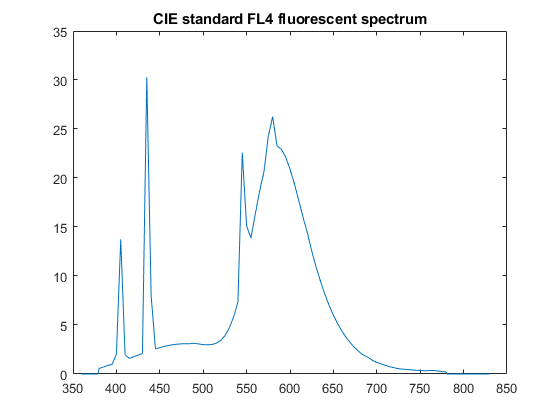

clf;plot(FL4.lam,FL4.val);
title('CIE standard FL4 fluorescent spectrum')

## `CIE_Illuminant_D`

Returns CIE standard daylight illuminant D as function of CCT.

% function rv = CIE_Illuminant_D(CCT,varargin)

**Input:** CCT is the desired color temperature. Must be in [4000, 25000]. 

           varargin: Name/Value pair 'lam',lam to define the desired wavelength table to which the illuminant spectrum will be interpolated. Default is 360:830 nm in 1 nm steps

**Output:** spectrum struct with fields lam (copy of input, or default 360:830), val and name (copy of input name)

**Usage Example:**

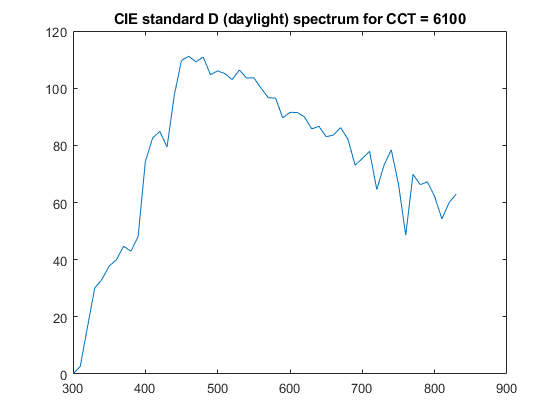

D6100 = CIE_Illuminant_D(6100,'lam',300:5:830);
clf;plot(D6100.lam,D6100.val);
title('CIE standard D (daylight) spectrum for CCT = 6100');

## `CODATA2018`

A struct with the most relevant physical constants for optics, as defined by [CODATA](http://www.codata.org/)

% function cd = CODATA2018()

**Input:** None

**Output:** Struct with fields:

`b`: Wien's wavelength displacement law constant

`bprime`: Wien frequency displacement law constant

`c`: speed of light in vacuum

`e`: elementary charge

`h`: Planck constant

`k`: Boltzmann constant

`me`: electron mass

`mn`: neutron mass

`mp`: proton mass

`NA`: Avogadro constant

`R`: molar gas constant

`Vm`: molar volume of ideal gas

`sigma`: Stefan-Boltzmann constant

`c1`: first radiation constant (2 pi h c^2)

`c1L`: first radiation constant for spectral radiance (2 h c^2)

`c2`: second radiation constant (h c / k)

Each field is a struct with fields `name, value, reluncertainty, absuncertainty, unit. `Most uncertainties are zero, since 2018.

**Usage Example:**

clear cd lambda freq pe c
cd = CODATA2018();
lambda = 500e-9; % in meters
c = cd.c.value % speed of light

c = 299792458

freq = c/lambda% frequency of 500 nm light about 600 THz

freq = 5.9958e+14

pe = freq * cd.h.value % energy of a 500 nm photon, in Joule

pe = 3.9729e-19

## `ComputeSpectrumColorimetry`

convenience function to compute XYZ, CCT and color rendering values in one call

% function rv = ComputeSpectrumColorimetry(s, varargin)

Takes the spectrum struct and adds fields with computed colorimetric values:

XYZ: struct with fields x, y, z, X, Y, Z as returned from CIE1931_XYZ(s)

CCT, dist_uv_Planck: color temperature and distance to Planck locus (may be NaN if out of CCT range)

CRI_all: struct with all 16 Ri and Ra as returned from CRI.FullCRI(s) (may be NaN if out of CCT range)

Ra: number, general CRI value

Also performs optional normalization to peak = 1

**Input:**

`s:` spectrum, struct with fields `lam `and `val.`

`varargin: `Name/Value pair: 'Normalize', 'peak' | 'off' (default) 

    Normalize -> 'peak' scales spectrum .val to have peak = 1

    Normalize -> 'off' leaves .val unchanged

**Output:**

`rv:` the spectrum, with added fields and possibly scaled `.val `field. Other fields in `s`, like e.g. `.name,` remain unchanged

**Usage Example:**

test = MakeSpectrum([400, 700],[1 1],'hopp',42); % hopp is just some field to show it remains
% test is almost CIE illuminant E, except for deepest blue and red
diffuseWhite = CIE_Illuminant('E');
tmp = ComputeSpectrumColorimetry(test,'XYZn',CIE1931_XYZ(diffuseWhite))

tmp = struct with fields:
               lam: [2×1 double]
               val: [2×1 double]
              hopp: 42
               XYZ: [1×1 struct]
                 x: 0.3334
                 y: 0.3340
                 u: 0.2103
                 v: 0.3160
                up: 0.2103
                vp: 0.4741
               CCT: 5.4527e+03
    dist_uv_Planck: -0.0041
           CRI_all: [1×1 struct]
                Ra: 95.5650
              Ldom: 556.7580
            purity: 0.0022
               Lab: [1×1 struct]
               Luv: [1×1 struct]


tmp.Lab % expect almost 100, and just a tiny bit greenish (a* < 0) and yellowish (b* > 0)

ans = struct with fields:
    L: 99.9772
    a: -0.3435
    b: 0.3085


tmp.Luv % expect same lightness, and small nonzero u and v

ans = struct with fields:
    L: 99.9772
    u: -0.3347
    v: 0.5164


## `CRI`

A class to compute color rendering indices. See [https://en.wikipedia.org/wiki/Color_rendering_index,](https://en.wikipedia.org/wiki/Color_rendering_index,) and CIE 13.3-1995 Technical Report

% classdef CRI < handle 

**Constructor:**

% function this = CRI()
cri = CRI()

cri =   CRI with properties:

    CRISpectra_: [1×16 struct]
    strict_5nm_: 0


loads the CRI reflectivity spectra into the read-only variable CRISpectra_

**SetStrict_5nm**

% function prev = SetStrict_5nm(this, yesno)
prev = cri.SetStrict_5nm(true)

prev = logical
   0


% do something
cri.SetStrict_5nm(prev); % restore previous state

sets the internal wavelength interval to 5 nm or 1 nm

**    Input:** yesno: logical (true -> 5nm, false -> 1nm)

**    Output:** prev: logical, the value before the call

**SingleRi**

computes a special Ri value

% function rv = SingleRi(this, spectrum, i)
FL4 = CIE_Illuminant('FL4');
D65 = CIE_Illuminant('D65');
cri.SingleRi(FL4,9) % Really really bad R9, fluorescent and saturated red don't work well

ans = -110.6599

cri.SingleRi(D65,9) % By definition, CIE D should work perfectly for CCT > 5000

ans = 99.9511

**Ra**

computes the general Ra, the by far most used value

% function [rv, Ri_1_8] = Ra(this, spectrum)
cri.Ra(FL4) % CRI is designed to give 51

ans = 51.5163

cri.Ra(D65) % by definition, 100

ans = 99.9866

**    Input: **a spectrum

    **Output: **rv: double, the Ra value.

                Ri_1_8: array of eight doubles, the individual Ri values of which Ra is the mean

**FullCRI**

computes the CRI for all sixteen reflectivity spectra. R1..R14 are defined in the standard, R15 is Asian skin, and R16 (my personal addition) is perfect white

% function rv = FullCRI(this, spectrum)
cri.FullCRI(FL4)

ans = struct with fields:
    Ri: [16×1 double]
    Ra: 51.5163


**    Input: **a spectrum

    **Output: **rv:  a struct with fields Ri (array of 16 doubles, the individual Ri values), and Ra (the general index)

**PlotCRISpectra**

plots the 16 reflectivity spectra

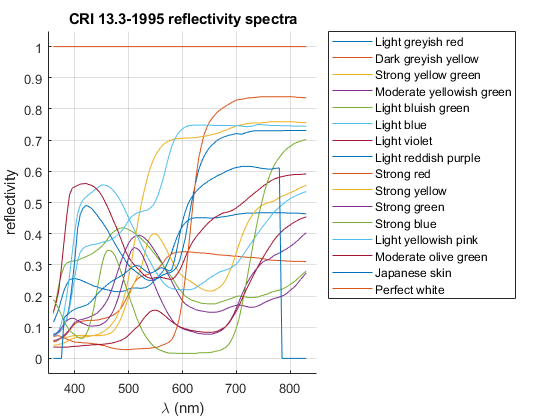

% function PlotCRISpectra(this)
cri.PlotCRISpectra();

**CRISpectra_**

a read-only property. An array of 16 structs with fields describing the individual spectra:

cri.CRISpectra_

ans = 1×16 struct array with fields:
    lam
    val
    name
    description
    munsell


## `Example_WhiteLED.m`

example script composing a white LED from blue and yellow, with supporting spectra blue.sre and yellow.sre. Run from Matlab environment and look at variables and figures.

% ExampleWhiteLED()

## `GaussSpectrum`

Creates a normalized Gaussian spectrum with given mean and standard deviation

% function rv = GaussSpectrum(lam_vec,mean,sdev,varargin)

**Input:** 

`lam_vec: `A vector of positive reals, strictly ascending

`mean: `Scalar positive number. Mean value of the distribution. May or may not be in the `lam_vec `range.

`sdev: `Scalar positive number. Standard deviation

`varargin: `Optional string argument '`val_only'.`

**Output:** 

`rv: `Spectrum struct, with additional `name `field. Except if optional argument '`val_only`' is present: Then, rv is a column vector of the values.

**Usage Example:**

see also example for `AddWeightedSpectra.`

GaussSpectrum(400:500,450,10)

ans = struct with fields:
     val: [101×1 double]
     lam: [101×1 double]
    name: 'Gauss spectrum for mean 450 nm and sdev 10 nm, normalized to peak = 1'


## `EvalSpectrum`

evaluates a spectrum via linear interpolation as function of wavelength. Vector input is possible 

% function rv = EvalSpectrum(s, lam)

**Input:**

`s:`  A valid spectrum

`lam:`  A scalar or vector of double

**Output:**

`rv:` A scalar or column vector of double, the interpolated value. Zero when outside the wavelength range

**Usage Example:**

s = GaussSpectrum(400:700,500,100);
v401 = s.val(2);
v402 = s.val(3);
fprintf('spectrum value at 401 nm: %g, at 402 nm: %g',v401, v402);

spectrum value at 401 nm: 0.612596, at 402 nm: 0.61866

interpolated = EvalSpectrum(s,401.5)

interpolated = 0.6156

outside = EvalSpectrum(s,399)

outside = 0

## `IntegrateSpectrum`

Compute weighted integral of spectrum. If weight omitted, compute just the integral.

% function rv = IntegrateSpectrum(spectrum, weight) 

Spectra in this library are always continuous, and assumed to be linear between the data points. First, spectrum and weight are multiplied. The result will have the wavelengths interweaved, and the multiplication result will be the product of the linearly interpolated individual values. The multiplication result is assumed to be linear between these interweaved points, just like every spectrum in this library. Accordingly, we integrate the multiplication result by simple trapezoidal rule.

This means, however, that even for simple linear spectra and weights, the integral depends on the wavelength resolution.

**Input:**

`spectrum:` A valid spectrum

`weight: `Optional argument, also a valid spectrum

**Output:**

`rv:` The integral ov `.val` over `.lam `of the multiplied spectrum (see `MultiplySpectra` for more info about details).If `eight` is omitted, just integrate the spectrum as-is.

**Usage Example:**

sunlight = PlanckSpectrum(200:10*1000, 5800); % approximate extraterrestrial solar spectrum, from deep UV up to 10 micron
visible = MakeSpectrum([360 780],[1 1]);
P_full = IntegrateSpectrum(sunlight);
P_visible = IntegrateSpectrum(sunlight, visible);
fprintf('the visible fraction is %.1f %%', P_visible / P_full * 100);

the visible fraction is 48.8 %

## `IsOctave`

Determines if code is running under GNU Octave (or Matlab)

% function rv = IsOctave()

**Output:** Returns logical 1 when running under GNU Octave, else returns logical 0

**Usage Example:**

IsOctave()

ans = logical
   0


## `IsSpectrum`

Checks if a spectrum is valid

% function yesno = IsSpectrum(s)

Checks if `s` is a struct with fields `lam `and `val`, which are both finite real 1D vectors, have same length, and that `lam` is strictly ascending and positive

**Input:**

`s:` Anything

**Output:**

`yesno:` logical, true if `s` meets the requirements

**Usage Example:**

s = PlanckSpectrum(200:2000,5600);
IsSpectrum(s)

ans = logical
   1


IsSpectrum(0)

ans = logical
   0


## `LDomPurity`

 Compute dominant wavelength and purity of a spectrum using `E = [ 1/3, 1/3]` as white point 

% function [ldom, purity] = LDomPurity(rhs)

**Input:**

`rhs:`  may be spectrum (struct with lam and val), or XYZ (struct with x and y), or array with length 2 

**Output:**

`ldom:` dominant wavelength in nm, i.e. the wavelength where the E -> x/y line intersects the monochromatic border. Negative if E -> x/y intersects magenta line, not the monochromatic border. 555 if x/y == E within circle of eps = 2.2e-16.

`purity: `purity, i.e. the E->x/y distance relative to E->border. 0 if x/y == E, 1 if x/y on border. Negative if E -> x/y intersects magenta line, not the monochromatic border.

**Usage Example:**

blue = GaussSpectrum(360:830,460,20);
[ldom,purity] = LDomPurity(blue) %#ok<ASGLU> % yes, LDom > LPeak for blue

ldom = 465.7497

purity = 0.9694

red = GaussSpectrum(360:830,630,20);
[ldom,purity] = LDomPurity(red) %#ok<ASGLU> % yes, LDom < LPeak for red

ldom = 614.0548

purity = 0.9999

magenta = AddSpectra(blue,red);
m_XYZ = CIE1931_XYZ(magenta);
[ldom,purity] = LDomPurity(m_XYZ) %#ok<ASGLU> % both values are negative

ldom = -554.0733

purity = -0.5550

green_xy = [0.16,0.80];
[ldom,purity] = LDomPurity(green_xy) %#ok<ASGLU> % x/y near border for about 530 nm

ldom = 530.5086

purity = 0.9925

[ldom,purity] = LDomPurity([1/3,1/3]) % ldom is arbitrary

ldom = 555

purity = 0

## `LinInterpol`

Computes linearly interpolated values of scalar tabulated function. Very similar to built in `interp1`, but uses faster C++ DLL under Matlab (on my machine, a factor of five faster).

Used internally as a helper function for higher level library functions, but exposed as a proper library function because it may well be useful to speed up computation in another context.

% function yq = LinInterpol(xx,yy,xq)

**Input:** 

`xx` is a 1D vector of numeric values which are not complex, and strictly ascending

`yy` is a 1D vector of numeric values which are not complex.

`xx` and `yy `are of same length and have at least two elements

`xq` is a 1D vector of numeric values which are not complex, and strictly ascending (the latter is NOT a requirement for `interp1`)

These preconditions are not checked.

**Output:**

`yq` is a vector of same length as `xq`*,* with linearly interpolated values. Zero if outside the `xx` range. 

**Usage Example:**

LinInterpol([1 2],[3 4],[-100,1,2,1.7])

ans =          0    3.0000    4.0000    3.7000


## `LinInterpolAdd4Async`

Computes linearly interpolated values of the sum of four input functions. Uses C++ DLL with multithreading under Matlab. On my machine, a factor of five faster than summing the result of `interp1 `calls, but not faster than summing the results of four `LinInterpol `calls. I still leave the function in place, there may be a difference for other input values and/or on another machine.

% function yq = LinInterpolAdd4Async(xx0,yy0,xx1,yy1,xx2,yy2,xx3,yy3,xq)

**Input:** 

`xx0 `is a 1D vector of numeric values which are not complex, and strictly ascending

`yy0 `is a 1D vector of numeric values which are not complex.

`xx0 `and `yy0 `are of same length and have at least two elements.

Same applies to the `xx1/yy1, xx2/yy2, xx3/yy3` pairs, but the `xx_ `arrays may all be different.

`xq `is a 1D vector of numeric values which are not complex, and strictly ascending (the latter is NOT a requirement for `interp1`!!)

**Output: **`yq` is a vector of same length as `xq`*,* with the sum of the four linearly interpolated values.

**Usage Example:**

LinInterpolAdd4Async([0 1],[1 1.1], [0 1],[2 2], [0 1],[3 3], [0 2],[4 4], [0, 1, 0.5])

ans =    10.0000   10.1000   10.0500


## `MacAdamEllipse`

Computes MacAdam ellipses and their parameters, for any x-y color point

% function [ell, g, a, b, theta_deg] = MacAdamEllipse(x, y, nstep, npoints)

MacAdam ellipses (see MacAdam, David L. „Visual Sensitivities to Color Differences in Daylight*“. *Journal of the Optical Society of America* 32, Nr. 5 (1. May 1942): 247. [https://doi.org/10.1364/JOSA.32.000247)](https://doi.org/10.1364/JOSA.32.000247)) show how close one can get, on average, when adjusting a tuneable color to a given color. The original paper reports results for 25 color points. Chickering (see Chickering, K. D. „Optimization of the MacAdam-Modified 1965 Friele Color-Difference Formula“. JOSA 57, Nr. 4 (1. April 1967): [https://doi.org/10.1364/JOSA.57.000537.](https://doi.org/10.1364/JOSA.57.000537.) and Chickering, K. D. „FMC Color-Difference Formulas: Clarification Concerning Usage“. JOSA 61, Nr. 1 (1. Januar 1971): 118. [https://doi.org/10.1364/JOSA.61.000118)](https://doi.org/10.1364/JOSA.61.000118)) gave parameters for a fitting model suggested by MacAdam and Friele. Here, we implemented what Chickering calls the "FMC-1" formula.

See script [TestMacAdamEllipses.m](matlab:open('TestMacAdamEllipses.m')) for a test, comparing our results to the OSRAM ColorCalculator by John Selverian.

**Input:**

`x, y:  `Color point of center of ellipse

`nstep: `number of MacAdam Steps (1 = just noticeable)

`npoints: `number of points to sample ellipse

**Output:**

`ell: `(2 x nPoints) array of double, ellipse points, in equi-angle steps around the ellipse center

`g:   `(2 x 2) double. The (symmetric) ellipse matrix, such that dxy * g * dxy' = distance in units of "just noteable differences"

`a:   `length of first half axis of 1-step ellipse

`b:   `length of second half axis of 1-step ellipse

`theta_deg: `tilt angle of first half axis, in degrees

**Usage Example:**

[ell, g, a, b, theta_deg] = MacAdamEllipse(0.33, 0.33, 10, 32);
fprintf('MacAdam matrix g11 = %g, g12 = %g, g22 = %g\n',g(1,1),g(1,2),g(2,2));

MacAdam matrix g11 = 651171, g12 = -287519, g22 = 243497


fprintf('Half axes a=%g, b = %g, tilt angle %g°\n',a, b, theta_deg);

Half axes a=0.00324631, b = 0.00111819, tilt angle 62.6674°


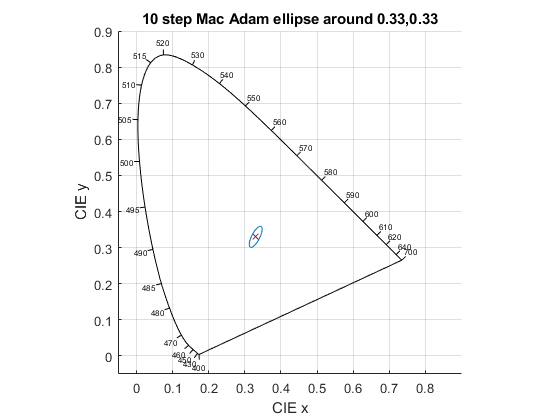

figure();
PlotCIExyBorder();
scatter(0.33,0.33,'x');
plot([ell(1,:),ell(1,1)],[ell(2,:),ell(2,1)]);
title('10 step Mac Adam ellipse around 0.33,0.33');

## `MakeSpectrum`

Creates a spectrum struct out of arrays `lam `and `val `and checks if they meet the requirements

% function rv = MakeSpectrum(lam, val, varargin)

**Input:** 

`lam `is a 1D vector of numeric values which are not complex, > 0, and strictly ascending

`val `is a 1D vector of numeric values which are not complex.

`lam `and `val `are of same length and have at least two elements.

The requirements are checked, an error thrown if violated

`varargin:` Name/Value pairs for additional fields

**Output:** 

`rv `is a spectrum struct with column vector fields `lam `and `val`*.*

**Usage Example:**

clear s
s = MakeSpectrum([400 700], [1 1],'name','flat spectrum') %#ok<NASGU> 

s = struct with fields:
     lam: [2×1 double]
     val: [2×1 double]
    name: 'flat spectrum'


## `MultiplySpectra`

Multiply two spectra, e.g. an LED spectrum with a transmission spectrum

% function rv = MultiplySpectra(lhs, rhs)

**Input:** `lhs, rhs: ` Valid spectrum structs. May or may not overlap.

**Output:** `rv: `Spectrum struct, modeling the product of *lhs(lambda) * rhs(lambda)*. The `rv.lam` field covers the overlap region, if any, where it contains all wavelengths from both inputs. The `rv.val `field contains the product of the respective interpolated values. There is no need to have zero values outside the overlap range, as zero is always assumed outside anyway. When there is no overlap, `rv` contains a single interval as the overall min/max wavelength range, with zero value.

**Usage Example:**

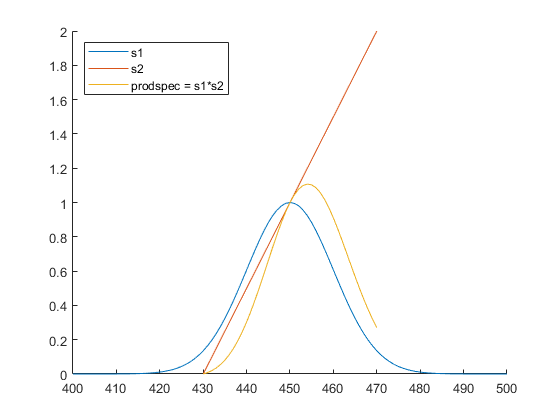

clear s1 s2 prodspec;
s1 = GaussSpectrum(400:500, 450,10);
s2 = MakeSpectrum([430 470],[0 2]);
prodspec = MultiplySpectra(s1, s2);
nfig = nfig + 1;
figure(nfig);
clf;
hold on;
plot(s1.lam, s1.val);
plot(s2.lam, s2.val);
plot(prodspec.lam, prodspec.val);
legend({'s1','s2','prodspec = s1*s2'},'Location','northwest');

## `PlanckLocus`

Compute the x/y, u/v, u'/v' coordinates of the Planck locus, as well as interpolation function objects for x/y, u/v, and the Judd lines (lines of equal correlated color temperature) in u/v.

% function rv = PlanckLocus()

**Input:** None

**Output:** Struct with fields:

`nT`: Number of temperature points (1001)

`invT`: Inverse absolute temperature values, from near zero (1e-11) to 0.002 (1/K), in equidistant steps. (The Planck locus points are approximately equidistant in 1/T, and not at all equidistant in T)

`T`: Absolute temperature values, from 1e11 K down to 500 K

`x`: CIE 1931 x color coordinate values of the Planck locus curve

y: CIE 1931 y color coordinate values of the Planck locus curve

u: CIE u color coordinate values of the Planck locus curve (to be used only for CCT computation purposes)

v: CIE v color coordinate values of the Planck locus curve (to be used only for CCT computation purposes)

up: CIE u' (u_prime) color coordinate values of the Planck locus curve 

vp: CIE v' (v_prime) color coordinate values of the Planck locus curve 

`xy_func`: A function object to compute interpolated values of the x/y color coordinates of the Planck locus. To be called like `xy = rv.xy_func(T) `where T is a scalar of vector of absolute temperatures, and returns an array of size `[2, length(T)] `with the interpolated x values as first column and the interpolated y values as second column. Returns `NaN `when `T` is out of range 500 .. 1e11

`uv_func`: Same as `xy_func`, except it returns u/v values.

`JuddLine_func`: A function object to compute interpolated values of the Judd line parameters. To be called like `jl = rv.JuddLine_func(T) `where T is a scalar, absolute temperature. Returns a struct with fields `u, v, du, dv `where [`u,v]` are the u/v coordinates of the Planck locus point for `T`, and `[du,dv] `is the Judd line direction, normalized to length 1. By definition, the Judd line is perpendicular to the Planck locus in u/v color space, and all color points on a Judd line are deemed to have same CCT (correlated color temperature). Note that the "allowed" meaningful range is +/- 0.05 u/v length units away from the Planck locus.

**Usage Example:**

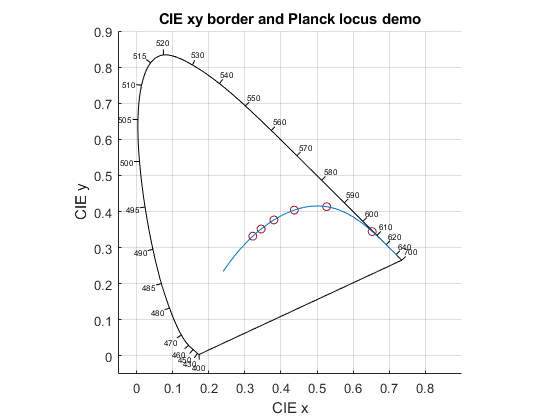

clear pl xb yb T xy
pl = PlanckLocus();
fh = figure();clf;
PlotCIExyBorder('Figure',fh);
hold on;
T = [1000 2000 3000 4000 5000 6000];
xy = pl.xy_func(T);
scatter(xy(:,1),xy(:,2));
plot(pl.x,pl.y);
axis equal;
grid on;
axis([-0.05 0.9 -0.05 0.9]);
xlabel('CIE x');
ylabel('CIE y');
title('CIE xy border and Planck locus demo')

## `PlanckSpectrum`

Generate blackbody spectrum for some absolute temperature.

% function rv = PlanckSpectrum(lam_vec, T, varargin)

**Input:** 

`lam_vec: `A wavelength vector, numeric, non-complex, positive, strictly ascending

`T: `Scalar real number, absolute temperature in K. May be `inf`, then returns `lam_vec.^(-4), `scaled to `localpeak1` (this is the high temperature limit of the shape of the long wavelength tail).

`varargin: `Name/Value pairs.

`    'normalize'` -> string, default `'globalpeak1'. `Allowed values:

`        'globalpeak1'`: scaled such that global peak would be 1.0 even if outside lambda range

`        'localpeak1'`: scaled such that the peak value is 1.0 for the given `lam_vec.` Not exactly identical if global peak is in range, due to discretization

`        'localflux1'`: scaled such that integral over `lam_vec` is 1.0

`        'radiance'`: scaled such that `rv` is blackbody spectral radiance, W/(wlu m²sr). wlu is wavelengthUnit, see below

                `'basic_radiance': `scaled such that `rv` is blackbody spectral basic radiance, differing from radiance by a factor of $n^2$. Same units as radiance.

`        'exitance'`: scaled such that rv is blackbody spectral exitance, W/(wlu m²). wlu is wavelengthUnit, see below

        The following Name/Value pairs define the refractive index of the medium in which the blackbody spectrum is measured. Default is air, with an index of 1.000277.

        For details of the physics, see the file `BlackbodySpectrumWithRefractiveIndex.pdf` or `BlackbodySpectrumWithRefractiveIndex.mlx `in this library.

        For dispersive cases, the wavelengths are given the same units as `lam_vec.`

`    'n_refr_const'` -> positive real scalar, default 1.000277. To obtain the spectrum in vacuum, set to 1.0

`    'n_refr_func' -> `function handle to dispersion function `n(lambda)`, default not used (returning NaN). 

                    Must have signature: `[n, dn_dlambda] = n_refr_func(lambda)` where `dn_dlambda `is the derivative, $\frac{\mathrm dn}{\mathrm d \lambda}$

`    'n_refr_table' -> `a valid spectrum, i.e. struct with appropriate fields lam and val. Default: unused

`    'n_refr_func' has precedence over 'n_refr_table', which has precedence over 'n_refr_const'`

`    'wavelengthUnit'` -> positive real, wavelength unit in meters, default 1e-9 (nanometers). Examples:

`        1e-9 `: `lam_vec `given in nm, returned spectrum is W / (nm m² sr) or W / (nm m²) for radiance/exitance scaling. `rv.XYZ` will be CIE XYZ values X, Y, Z, x, y

                `1e-6: lam_vec `given in µm, returned spectrum is W / (µm m² sr) or W / (µm m²) for radiance/exitance scaling.

**Output:** Spectrum struct with fields

`lam: `Same as `lam_vec,` but column vector.

`val: `The spectral values, column vector of same length, normalized according to `'normalize'` (default: global peak 1.0).

`name:` string, an appropriate name

`XYZ: `(only for nanometer wavelength units): Struct with `X,Y,Z `tristrimulus values, and `x,y,z CIE 1931 color coordinates.`

**Usage Example:**

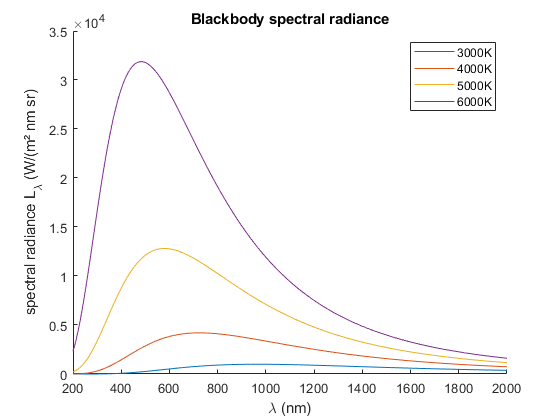

clear bb T 
nfig = nfig + 1;
figure(nfig);
clf;
hold on;
for T = [3000 4000 5000 6000]
    bb = PlanckSpectrum(200:2000,T,'normalize','radiance');
    plot(bb.lam,bb.val);
end
xlabel('\lambda (nm)');
ylabel('spectral radiance L_\lambda (W/(m² nm sr)')
legend({'3000K','4000K','5000K','6000K'})
title('Blackbody spectral radiance')

## `PlotCIExyBorder`

plotting the CIE x/y "color horseshoe", with optional ticks and other options 

% function [ah, fh] = PlotCIExyBorder(varargin)

Plot the CIE x/y "color horseshoe" into a new figure or a given figure or axes handle. Various options are available to control the look. Re-use the figure and/or axes handle for further plotting into the same figure

**Input:**

`varargin`: Name/Value pairs:

    `'Handle'`: valid figure handle to use for the plot. Current hold state will be restored

    `'Axes'`  : valid axes handle to use for the plot. Current hold state will be restored. Overrides `'Handle'`

    `'LineSpec'` : valid `LineSpec `string (see `plot` documentation), e.g. `'--b'` for dashed blue lines, see 'plot' documentation.

    `'PlotOptions':` cell array of valid plot options, e.g. `{'Color',[0.5 0.5 0.5],'LineWidth',2}`

    `'Ticks'` : array of wavelength values where ticks and labels are plotted. Reasonable default. Say `...,'Ticks',[],...` to suppress

    `'TickFontSize':` number, obvious meaning. Default: `6`

**Output:**

`ah:` the axis handle

`fh:` the figure handle

**Usage Example: **(see also the example for PlanckLocus)

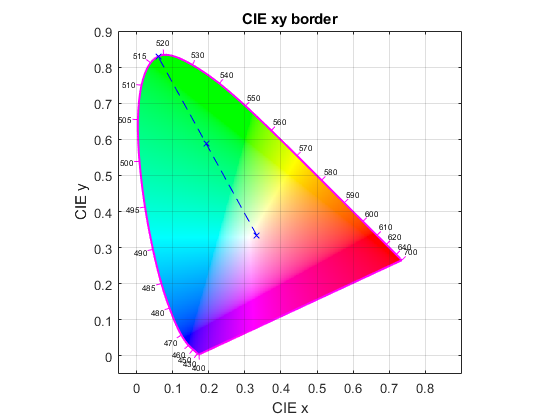

[ah, fh] = PlotCIExyBorder('LineSpec','m','PlotOptions',{'LineWidth',1.5},'ColorFill',true);
green = ComputeSpectrumColorimetry(GaussSpectrum(450:600,520,30));
% find the point on the monochromatic border corresponding to lDom
load('CIE1931_lam_x_y_z.mat','CIE1931XYZ');
xPure = LinInterpol(CIE1931XYZ.lam, CIE1931XYZ.xBorder, green.Ldom);
yPure = LinInterpol(CIE1931XYZ.lam, CIE1931XYZ.yBorder, green.Ldom);
% plot line from white point, to x/y of green, to border at green.lDom
plot([1/3,green.XYZ.x,xPure], [1/3,green.XYZ.y,yPure],'--bx');

## `ReadLightToolsSpectrumFile`

Read LightTools .sre files, as supplied by many LED vendors. Reads also simple ASCII 2-column tables with any text header

% function rv = ReadLightToolsSpectrumFile( fn )

LightTools .sre files are simple ASCII 2 column text files, with a text header. The files `blue.sre `and `yellow.sre `are examples. 

LightTools .sre files have the option to be photometric, i.e. values are luminous flux, whereas all spectra in this library are radiometric. If it is photometric, ReadLightToolsSpectrumFile rescales the values properly to radiometric. There is also an option to be discrete, i.e. a spectrum of narrow lines. ReadLightToolsSpectrumFile converts such files to a continuous spectrum with very narrow triangular peaks.

ReadLightToolsSpectrumFile can also be used to read a spectrum from an ASCII file which starts with any number of text header lines, i.e. lines whose first non-whitespace character is not a '0'..'9' digit, followed by lines with two numbers each. 

The last line may or may not be terminated with a newline, i.e. the last line may be empty.

**Input:**

`fn:` File name. Extension must be supplied, is not automatically added.

**Output:**

`rv:` The spectrum

**Usage Example:**

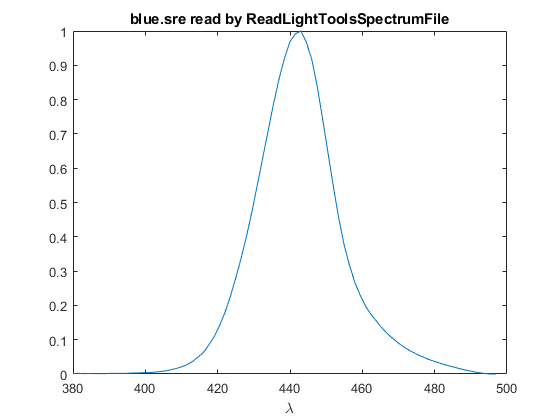

blue = ReadLightToolsSpectrumFile( 'blue.sre' );
figure; clf;
plot(blue.lam, blue.val);
xlabel('\lambda'); title('blue.sre read by ReadLightToolsSpectrumFile');

## `RGBLEDSpectrum`

A class that models R,G,B LED spectra at operating conditions, based only on information from data sheets (and spectra as part of ray files, where available).

% LED = RGBLEDSpectrum(base_spectrum, T_group, I_group); % constructor call, 
%       % with typical spectrum, grouping temperature and grouping current from data sheet.
% LED.SetCharacteristicCurves(I_vs_U, relFlux_vs_I, relFlux_vs_Temp, delta_ldom_vs_I, delta_ldom_vs_Temp, deltaU_vs_Temp)
%       % the characteristic curves, to be sampled as tables from the data sheet
% LED.SetBinningParameters(U_binning,Phiv_binning,ldom_binning);
%       % set individual LED parameters from binning, i.e. measurement at grouping conditions
% spec = LED.OperatingSpectrum(I_operating, T_operating);
%       % obtain the actual LED spectrum at operating current and temperature.

For the purposes of this class, a red, green or blue LED has a spectrum whose shape is invariant, like the typical spectrum shown on a data sheet. (The actual shape varies a little from LED to LED, and with operating temperature and current, but this effect is neglected here). For some LEDs, the spectra are available as text files as part of the ray file package.

For a given LED, the data sheet shows how, typically, current varies with voltage, relative flux and dominant wavelength vary with current, and flux, wavelength and voltage vary with temperature. Those curves need to be sampled by the user from the data sheet (there is "digitizer" software available to ease that chore, e.g. as part of the LightTools utilities).

LEDs are binned by measuring flux, dominant wavelength and voltage at grouping conditions. The variations just described show how an LED's properties vary from these binning values according to operating conditions.

The use case of this class is to 

- characterize an LED model by its typical spectrum, and its typical parameter variation (change of voltage, wavelength and flux vs. current and temperature)

- characterize an invidual LED from this model by its binning parameters (voltage, wavelength and flux at grouping current and temperature)

- apply arbitrary operating parameters (current and junction temperature) to that specific LED

- obtain the estimated spectrum of that specific LED at that specific operating parameters

An additional refinement would be to specify operating solder point temperature instead of junction temperature, using the LED's thermal resistance and the waste heat at operating conditions to estimate actual junction temperature. This, however, requires iteration and is planned for a future revision.

**Input:**

`rhs:` the right hand side

**Output:**

`lhs:` the left hand side

**Usage Example:**

See script file `TestRGBLED.mlx `on how to obtain this figure for a certain blue LED:

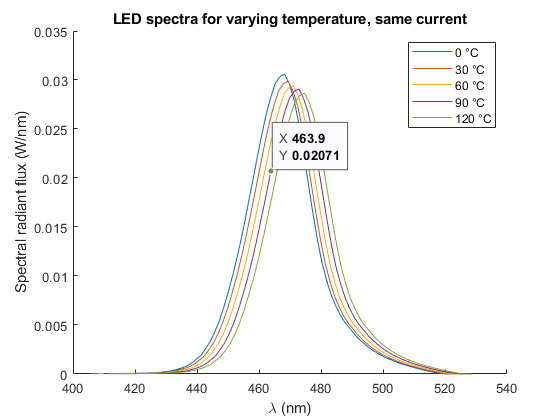

## `ShiftToLdom`

Shifts the wavelength of a spectrum such that the result has a desired dominant wavelength

% function [spec_out, delta_lam] = ShiftToLdom(spec_in, ldom)

Given an input spectrum, iteratively adds/subtracts a constant wavelength to the wavelength range, until the resulting spectrum has the desired dominant wavelength

**Input:**

`spec_in:` A valid spectrum, at least partially in the visible range

`ldom: `The desired dominant wavelength in nanometes, within `[400,695].`

**Output:**

`spec_out:` The shifted spectrum

`delta_lam: `The applied shift

**Usage Example:**

clear;
blue = ReadLightToolsSpectrumFile('blue.sre');
dl0 = LDomPurity(blue)

dl0 = 447.3515

green = ShiftToLdom(blue, 540);
LDomPurity(green)

ans = 540.0000

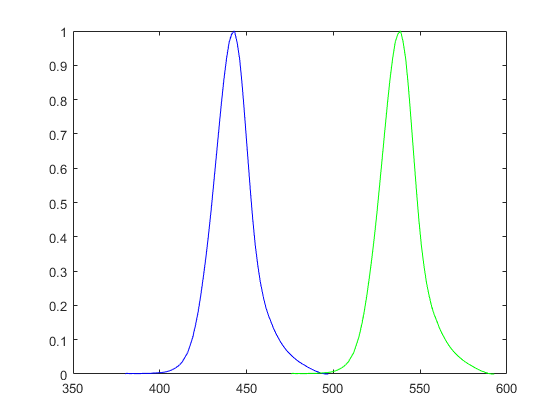

figure();
clf;
plot(blue.lam, blue.val,'b');
hold on; 
plot(green.lam, green.val,'g');

## `SolarSpectrum`

Standard ASTM solar spectra: extraterrestrial (AM0), global tilted AM1.5 and direct/circumsolar AM1.5

% function rv = SolarSpectrum(type)

Returns solar spectra as standardized in ASTM G173-03, as provided by NREL, [https://www.nrel.gov/grid/solar-resource/spectra-am1.5.html](https://www.nrel.gov/grid/solar-resource/spectra-am1.5.html)

There are four spectra: Extraterrestrial irradiance (AM0 = air mass zero), AM 1.5 global tilted irradiance (irradiance on a tilted plane from all directions, with an effective air layer of 1.5 times vertical), and AM 1.5 direct (same as before, but restricted to directions from and around the sun). In addition, there is extraterrestrial irradiance for an extended wavelength range from 119.5 nm to 1 mm = 1,000,000 nm.

**Input:**

`type:` A string to determine which spectrum to return. Allowed values are 'AM0', 'AM15_GlobalTilt', 'AM15_Direct_Circumsolar' and 'AM0_ASTM_E490'.

**Output:**

`rv:` The requested spectrum, with fields `lam, val, name.`

**Usage Example:**

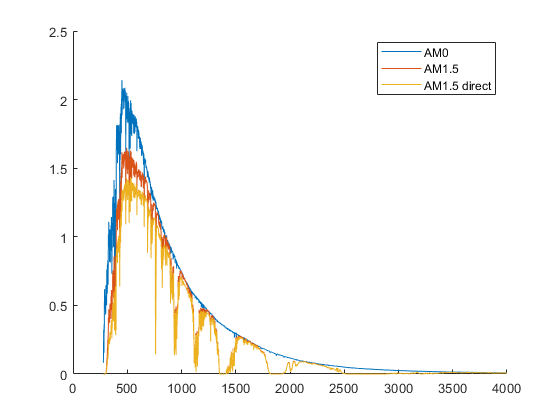

AM0 = SolarSpectrum('AM0');
AM15 = SolarSpectrum('AM15_GlobalTilt');
AM15_direct = SolarSpectrum('AM15_Direct_Circumsolar');
figure();clf;hold on;
plot(AM0.lam, AM0.val);
plot(AM15.lam, AM15.val);
plot(AM15_direct.lam, AM15_direct.val);
legend({'AM0','AM1.5','AM1.5 direct'});

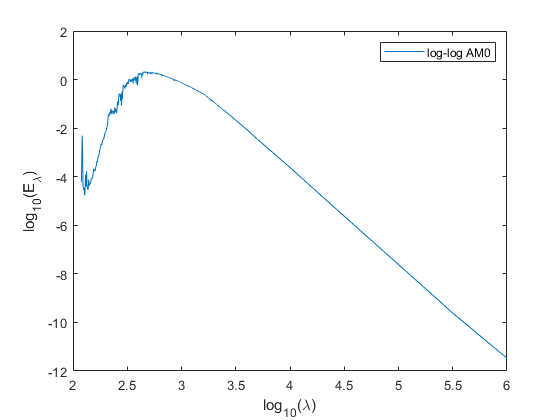

AM0_E490 = SolarSpectrum('AM0_ASTM_E490');
figure();clf;
plot(log10(AM0_E490.lam),log10(AM0_E490.val));
xlabel('log_{10}(\lambda)');
ylabel('log_{10}(E_\lambda)');
legend('log-log AM0');

## `SpectrumSanityCheck`

Checks requirements for a spectrum variable, and returns a sanitized version of the variable, with column vectors `lam` and `val`.

% function [ok, msg, rv] = SpectrumSanityCheck(spec, varargin)

**Input:** 

`spec`  is a spectrum which should adhere to the requirements above.

`varargin `are optional name/value pairs:

    '`doThrow`', logical, default: true. If there is an error: If flag is true, throws error exception, else returns false in `ok` and an error message in *msg*.

    '`doStrip`', logical, default: false: If true returns `rv` with only the `lam` and `val` fields, else returns `rv` with all fields of input `spec`

**Output:** 

`ok`: Logical. True if there are no requirement violations, else false

`msg`*: *Character string. Empty string if there are no requirement violations, else diagnostic message.

`rv`*: *A spectrum struct where `lam` and `val `are same as in `spec `except that both are always column vectors. When the `doStrip `flag is false, also has all other fields of `spec`*. *At requirement violation, is empty array.

**Usage Example:**

clear good bad ok1 msg1 rv1 ok2 msg2 rv2
good = MakeSpectrum([400 700], [1 1]);
[ok1, msg1, rv1] = SpectrumSanityCheck(good)

ok1 = logical
   1



msg1 =

     []



rv1 = struct with fields:
    lam: [2×1 double]
    val: [2×1 double]


bad = struct('lam', [1, 2, 1], 'val', [0 0 0]);
[ok2, msg2, rv2] = SpectrumSanityCheck(bad, 'doThrow', false)

ok2 = logical
   0


msg2 = 'lam must be strictly ascending'


rv2 =

     []



## `TestLinInterpol`

A script to test the `LinInterpol` and `LinInterpolAdd4Async` functions, also measuring run times.

**Input:** none

**Output:** diagnostic text

**Usage Example:**

TestLinInterpol

LinInterpol elapsed time:1.2789e-05
interp1 elapsed time: 3.8792e-05, diffnorm = 0
LinInterpolAdd4Async elapsed time: 8.3944e-05
4 x LinInterpol elapsed time: 4.7378e-05, diffnorm = 0
4 x interp1 elapsed time: 0.00013866, diffnorm = 0


## `Vlambda`

Returns V(lambda), CIE 1924 as a spectrum

% function rv = Vlambda()

In steps of 1 nm from 360 nm to 830 nm

**Input: **none

**Output:**

`rv:` V(lambda) as spectrum in steps of 1 nm from 360 nm to 830 nm

**Usage Example:**

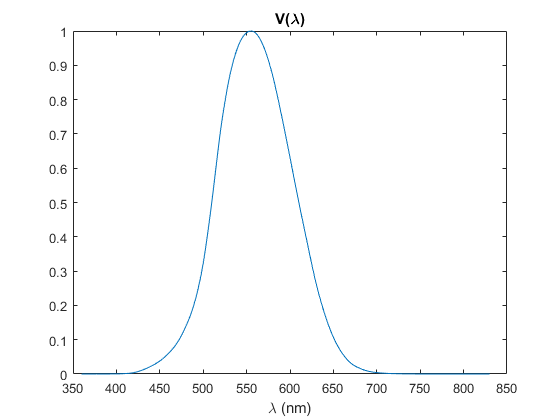

vl = Vlambda();
figure(); clf;
plot(vl.lam, vl.val);
xlabel('\lambda (nm)');
title('V(\lambda)')

## `WriteLightToolsSpectrumFile`

Write LightTools .sre spectrum file, to assign to a source

% function WriteLightToolsSptrumFile(spectrum, filename, varargin)

**Input:**

`spectrum`: A valid spectrum with .lam and .val fields. See Spectrum requirements.

    If spectrum has other fields which are simple strings or numeric values, they will be written as named comments. E.g. if spectrum.name == 'My LED' then '# name: My LED' will be written.

`filename`: name of the spectrum file. `'.sre'` is appended if necessary

optional arguments: Name-Value pairs

    `'mode'`: string, only allowed value is `'discrete'. `Default spectrum mode is continuous.

    `'comment'` : string or cell array of strings, will be written as comment(s)

**Output:** none

**Usage Example:**

s = PlanckSpectrum(400:700,5600);
WriteLightToolsSpectrumFile(s,'Planck5600.sre');

will write `Planck5600.sre`, with the first lines being

`# LightTools spectrum file, created 13-Oct-2019 15:16:16`

`# name: Planck blackbody spectrum for T = 5600 K, normalized to global peak = 1`

`dfat 1.0`

`dataname: Planck blackbody spectrum for T = 5600 K, normalized to global peak = 1`

`continuous`

`radiometric`

`400	0.838583`

`401	0.841573`

## `template for copy paste`

short 

% 

long

**Input:**

`rhs:` the right hand side

**Output:**

`lhs:` the left hand side

**Usage Example:**